%% Hw3-Part2.1 %% good
clc; clear; close all;

%% Parameter settings
N = 400;            % Total number of data points
T0 = 200;           % True change point
rho = 0.8;          % AR(1) coefficient
phi = pi/4;         % AR(2) pole angle
sigma_alpha = 1;    % AR(1) noise standard deviation
sigma_beta = 1;     % AR(2) noise standard deviation
MC = 4000;         % Number of Monte Carlo simulations

% Correct AR(2) coefficients
a1 = rho * cos(phi);    % AR(2) coefficient a1
a2 = -rho^2 / 4;        % AR(2) coefficient a2 (note the negative sign)

%% Monte Carlo simulation
mse_values = zeros(MC, 1); % Store MSE results
T_hat_estimations = zeros(MC, 1); % Store estimated T_hat for each experiment

for mc = 1:MC
    % Generate AR(1) process (n ≤ T0)
    x = zeros(N, 1);
    x(1) = sqrt(sigma_alpha) * randn; % Initial value
    for n = 2:T0
        x(n) = rho * x(n-1) + sqrt(sigma_alpha) * randn;
    end
    
    % Generate AR(2) process (n > T0)
    % Correctly initialize the first two points and generate recursively
    x(T0+1) = sqrt(sigma_beta) * randn; % β*x[T0+1]
    x(T0+2) = sqrt(sigma_beta) * randn; % β*x[T0+2]
    for n = T0+3:N
        x(n) = a1 * x(n-1) + a2 * x(n-2) + sqrt(sigma_beta) * randn;
    end

    %% Iterate over all possible change points T_hat, calculate posterior probabilities
    posterior_prob = zeros(N, 1); % Store posterior probability for each T_hat
    
    for T_hat = 2:N-2
        % Residuals for AR(1) segment (n=2 to T_hat)
        e_AR1 = x(2:T_hat) - rho * x(1:T_hat-1);
        RSS1 = sum(e_AR1.^2);
        
        % Residuals for AR(2) segment (n=T_hat+3 to N)
        e_AR2 = x(T_hat+3:N) - a1 * x(T_hat+2:N-1) - a2 * x(T_hat+1:N-2);
        RSS2 = sum(e_AR2.^2);
        
        % Calculate posterior probability P(T_hat | X) based on RSS
        posterior_prob(T_hat) = exp(-0.5 * (RSS1 + RSS2));
    end
    posterior_prob_smooth = movmean(posterior_prob, 5); % 5-point moving average smoothing
    % Find the T_hat corresponding to the maximum posterior probability (MAP estimate)
    [~, T_hat_opt] = max(posterior_prob_smooth(2:N-2));
    T_hat_opt = T_hat_opt + 1; % Adjust index offset
    
    % Record the T_hat corresponding to maximum posterior probability in each experiment
    T_hat_estimations(mc) = T_hat_opt;
    
    % Calculate Mean Squared Error (MSE)
    mse_values(mc) = (T_hat_opt - T0)^2;
end

%% Calculate Mean Squared Error (MSE)
MSE = mean(mse_values);
fprintf('Monte Carlo computed MSE: %.4f\n', MSE);

Monte Carlo computed MSE: 784.8597


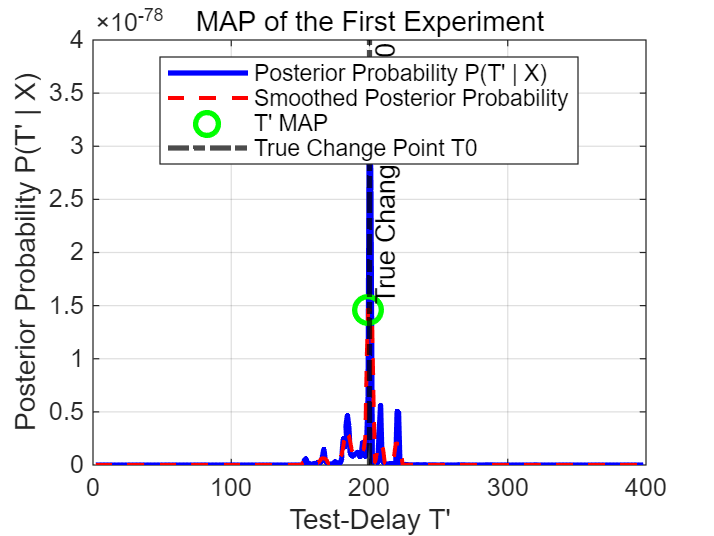


%% Plot the maximum posterior probability graph from the first experiment
figure;
plot(2:N-2, posterior_prob(2:N-2), 'b', 'LineWidth', 2); % Plot posterior probability
hold on;
plot(2:N-2, posterior_prob_smooth(2:N-2), '--r', 'LineWidth', 1.5); % Plot smoothed posterior probability
plot(T_hat_opt, posterior_prob_smooth(T_hat_opt), 'go', 'MarkerSize', 10, 'LineWidth', 2); % Mark the maximum posterior point
xline(T0, '-.k', 'True Change Point T0', 'LineWidth', 2); % Mark the true change point T0
title('MAP of the First Experiment');
xlabel('Test-Delay T''');
ylabel('Posterior Probability P(T'' | X)');

% Modify legend
legend('Posterior Probability P(T'' | X)', 'Smoothed Posterior Probability', 'T'' MAP', 'True Change Point T0', 'Location', 'Best');

grid on;

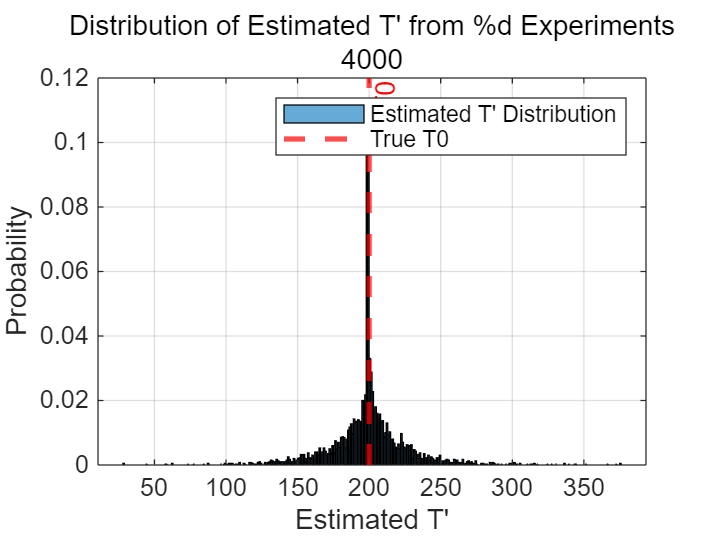


%% Plot the distribution of maximum posterior probability estimates after 1000 experiments
figure;
histogram(T_hat_estimations, 'Normalization', 'probability', 'BinWidth', 1);
hold on;
xline(T0, '--r', 'T0', 'LineWidth', 2); % Mark the true change point location
title('Distribution of Estimated T'' from %d Experiments', MC);
xlabel('Estimated T''');
ylabel('Probability');
legend('Estimated T'' Distribution', 'True T0');
grid on;